% Space out points on the x-axis 
% Starting from 12.5 up to 256.
t = linspace(12.5/256, 12.5, 256)';

% Decays are biologically fixed
tau1 = 2.14; 
tau2 = 0.69;

% Compute the column vectors of the A matrix 
a1 = exp(-t / tau1);
a2 = exp(-t / tau2);

% IRF centered at 2ns
mu = 2;

% Full with half max = 340ps (defining Gaussian for IRF)
fwhm = 0.34;

% Convert FWHM to standard deviation using known formula
% FWHM = 2 * sigma * sqrt{2 ln(2)}
sigma = fwhm / (2*sqrt(2*log(2)));

% Define IRF using Gaussian standard deviation formula
% Evenly space points
irf = exp(-(t - mu).^2 / (2*sigma^2));
irf = irf / sum(irf);

% Apply convolution to each vector of A
% 'Same' ==> we get col vector of length 256
a1_conv = conv(a1, irf, 'same');
a2_conv = conv(a2, irf, 'same');

% A matrix
A = [a1_conv, a2_conv,  ones(256,1)];
A_fig = [a1_conv, a2_conv];
Apinv = (A'*A) \ A';

%A = [a1,a2];

% % Number of photons (F_sensor)
% F_0 = 300000;
% 
% % Ground truth P1 value
% p1_real = 0.45;
% p2_real = 1-p1_real;


% x and y axis: P1 and Photon count resp.
p1_vec = linspace(0.4, 0.6, 60);   
F0_vec = linspace(1e5, 1e6, 60); 

% Pre allocate 0s for 60 x 60 grid
P1hat_grid = zeros(numel(F0_vec), numel(p1_vec));


% Fix photon count
% Iterate over all P1 values
% 500 estimates of fitted p1
% Calculate fitted p1 median and add to grid
% Go to next # of photon count then repeat
for i = 1:numel(F0_vec)
    F_0 = round(F0_vec(i));
    fprintf('i = %d / %d  (F_0 = %d)\n', i, numel(F0_vec), F_0);
    for j = 1:numel(p1_vec)
        p1_real = p1_vec(j);
        p2_real = 1-p1_real;
        % Components of C matrix
        c1 = F_0*p1_real;
        c2 = F_0*p2_real;
        % Composed of F0P1 and F0P2
        c = [c1,c2]';
        % Gives: Measured Vals = F0P1e^{-t/tau1}+F0P2e^{-t/tau2}
        y = A_fig * c;
        prob = y / sum(y);

        % vectorized: all 500 trials at once
        lambda = F_0 * prob;
        Y = poissrnd(repmat(lambda,1,500));     % 256 x 500, each column = one histogram
        Chat = Apinv * Y;                   % 2 x 500, each column = one [c1;c2] fit
        P1h  = Chat(1,:)./(Chat(1,:)+Chat(2,:));  % 1 x 500, all 500 P1 estimates

        P1hat_grid(i,j) = median(P1h);
    end
end

i = 1 / 60  (F_0 = 100000)
i = 2 / 60  (F_0 = 115254)
i = 3 / 60  (F_0 = 130508)
i = 4 / 60  (F_0 = 145763)
i = 5 / 60  (F_0 = 161017)
i = 6 / 60  (F_0 = 176271)
i = 7 / 60  (F_0 = 191525)
i = 8 / 60  (F_0 = 206780)
i = 9 / 60  (F_0 = 222034)
i = 10 / 60  (F_0 = 237288)
i = 11 / 60  (F_0 = 252542)
i = 12 / 60  (F_0 = 267797)
i = 13 / 60  (F_0 = 283051)
i = 14 / 60  (F_0 = 298305)
i = 15 / 60  (F_0 = 313559)
i = 16 / 60  (F_0 = 328814)
i = 17 / 60  (F_0 = 344068)
i = 18 / 60  (F_0 = 359322)
i = 19 / 60  (F_0 = 374576)
i = 20 / 60  (F_0 = 389831)
i = 21 / 60  (F_0 = 405085)
i = 22 / 60  (F_0 = 420339)
i = 23 / 60  (F_0 = 435593)
i = 24 / 60  (F_0 = 450847)
i = 25 / 60  (F_0 = 466102)
i = 26 / 60  (F_0 = 481356)
i = 27 / 60  (F_0 = 496610)
i = 28 / 60  (F_0 = 511864)
i = 29 / 60  (F_0 = 527119)
i = 30 / 60  (F_0 = 542373)
i = 31 / 60  (F_0 = 557627)
i = 32 / 60  (F_0 = 572881)
i = 33 / 60  (F_0 = 588136)
i = 34 / 60  (F_0 = 603390)
i = 35 / 60  (F_0 = 618644)
i = 36 / 60  (F_0 = 633898)
i

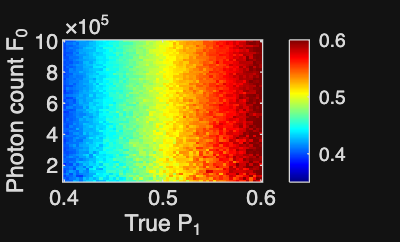



 imagesc(p1_vec, F0_vec, P1hat_grid); 
 set(gca,'YDir','normal'); clim([0.35 0.6]); colorbar;
 colormap(jet); 
 xlabel('True P_1'); ylabel('Photon count F_0');

 bias = P1hat_grid - repmat(p1_vec, numel(F0_vec), 1);
 fprintf('Max |bias|: %.3e\n', max(abs(bias(:))));

Max |bias|: 4.547e-02



 
% % row = take the slice from some grid row (of 60)
% row = 15;  
% % Plot known p1 values against fitted p1 values at fixed photon count
% plot(p1_vec, P1hat_grid(row,:), 'o') 
% hold on
% % Plot line of best fit x = y from [0,1]
% plot([0 1], [0 1], 'k--')           
% hold off
% % set axis equal to each other
% axis equal
% % fix max vals plotted
% xlim([0 1]); ylim([0 1])
% xlabel('True P_1'); ylabel('Fitted P_1')
% title(sprintf('Recovery at F_0 = %.0f', F0_vec(row)))
% legend('fitted', 'y = x', 'Location','northwest')
% grid on
